% Messing with closed form of bezier
clear all; close all; clc;

% bezier desciption
z_des = .5;

% 5-pt bezier curve
% P3_ = (8/3)*z_des; 
% P_ = [0 0 P3_ 0 0];

% 7-pt bezier curve
P3_ = (16/5)*z_des; 
P_ = [1 1 1 P3_ -1 -1 -1];

n = length(P_);

% init variables
syms t
syms P [1 n]

B = build_Bezier(n,t,P) % bezier curve

$$B = P_{7}\,t^{6}+P_{1}\,{\left(t-1\right)}^{6}-6\,P_{2}\,t\,{\left(t-1\right)}^{5}-6\,P_{6}\,t^{5}\,\left(t-1\right)+15\,P_{3}\,t^{2}\,{\left(t-1\right)}^{4}-20\,P_{4}\,t^{3}\,{\left(t-1\right)}^{3}+15\,P_{5}\,t^{4}\,{\left(t-1\right)}^{2}$$

dBdt = diff(B,t)        % bezier derivative

$$dBdt = 6\,P_{7}\,t^{5}-6\,P_{6}\,t^{5}+6\,P_{1}\,{\left(t-1\right)}^{5}-6\,P_{2}\,{\left(t-1\right)}^{5}-30\,P_{2}\,t\,{\left(t-1\right)}^{4}+30\,P_{3}\,t\,{\left(t-1\right)}^{4}-30\,P_{6}\,t^{4}\,\left(t-1\right)+15\,P_{5}\,t^{4}\,\left(2\,t-2\right)+60\,P_{3}\,t^{2}\,{\left(t-1\right)}^{3}-60\,P_{4}\,t^{2}\,{\left(t-1\right)}^{3}-60\,P_{4}\,t^{3}\,{\left(t-1\right)}^{2}+60\,P_{5}\,t^{3}\,{\left(t-1\right)}^{2}$$

ddBddt = diff(dBdt,t)      % bezier double derivative

$$ddBddt = 30\,P_{5}\,t^{4}-60\,P_{6}\,t^{4}+30\,P_{7}\,t^{4}+30\,P_{1}\,{\left(t-1\right)}^{4}-60\,P_{2}\,{\left(t-1\right)}^{4}+30\,P_{3}\,{\left(t-1\right)}^{4}-120\,P_{2}\,t\,{\left(t-1\right)}^{3}+240\,P_{3}\,t\,{\left(t-1\right)}^{3}-120\,P_{4}\,t\,{\left(t-1\right)}^{3}-120\,P_{6}\,t^{3}\,\left(t-1\right)-60\,P_{4}\,t^{3}\,\left(2\,t-2\right)+120\,P_{5}\,t^{3}\,\left(2\,t-2\right)+180\,P_{3}\,t^{2}\,{\left(t-1\right)}^{2}-360\,P_{4}\,t^{2}\,{\left(t-1\right)}^{2}+180\,P_{5}\,t^{2}\,{\left(t-1\right)}^{2}$$


% eval stuff
fprintf("-----------------------")

-----------------------

fprintf("B(0) =")

B(0) =

disp(subs(B,t,0))

$$P_{1}$$

fprintf("B(1) =")

B(1) =

disp(subs(B,t,1))

$$P_{7}$$


fprintf("-----------------------")

-----------------------

fprintf("dBdt(0) =")

dBdt(0) =

disp(subs(dBdt,t,0))

$$6\,P_{2}-6\,P_{1}$$

fprintf("dBdt(1) =")

dBdt(1) =

disp(subs(dBdt,t,1))

$$6\,P_{7}-6\,P_{6}$$


fprintf("-----------------------")

-----------------------

fprintf("ddBddt(0) =")

ddBddt(0) =

disp(subs(ddBddt,t,0))

$$30\,P_{1}-60\,P_{2}+30\,P_{3}$$

fprintf("ddBddt(1) =")

ddBddt(1) =

disp(subs(ddBddt,t,1))

$$30\,P_{5}-60\,P_{6}+30\,P_{7}$$


% see what the value of the midpoint is
fprintf("-----------------------")

-----------------------

B_ = subs(B,P,P_)

$$B\_ = 6\,t^{5}\,\left(t-1\right)-6\,t\,{\left(t-1\right)}^{5}+{\left(t-1\right)}^{6}+15\,t^{2}\,{\left(t-1\right)}^{4}-32\,t^{3}\,{\left(t-1\right)}^{3}-15\,t^{4}\,{\left(t-1\right)}^{2}-t^{6}$$

dBdt_ = subs(dBdt,P,P_)

$$dBdt\_ = 30\,t^{4}\,\left(t-1\right)-15\,t^{4}\,\left(2\,t-2\right)-36\,t^{2}\,{\left(t-1\right)}^{3}-156\,t^{3}\,{\left(t-1\right)}^{2}$$

ddBddt_ = subs(ddBddt,P,P_)

$$ddBddt\_ = 120\,t^{3}\,\left(t-1\right)-72\,t\,{\left(t-1\right)}^{3}-216\,t^{3}\,\left(2\,t-2\right)-576\,t^{2}\,{\left(t-1\right)}^{2}$$

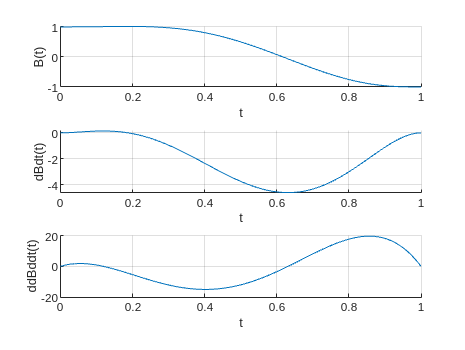


% plot some stuff
tspan = 0:0.01:1;
B_t = zeros(length(tspan),1);
dBdt_t = zeros(length(tspan),1);
ddBddt_t = zeros(length(tspan),1);

for i = 1:length(tspan)
    t_ = tspan(i);

    b = subs(B,t,t_);
    b = subs(b,P,P_);
    B_t(i) = double(b);

    dbdt = subs(dBdt,t,t_);
    dbdt = subs(dbdt,P,P_);
    dBdt_t(i) = double(dbdt);

    ddbddt = subs(ddBddt,t,t_);
    ddbddt = subs(ddbddt,P,P_);
    ddBddt_t(i) = double(ddbddt);
end

figure(1);
subplot(3,1,1)
hold on; grid on;
plot(tspan,B_t)
xlabel("t")
ylabel("B(t)")

subplot(3,1,2)
hold on; grid on;
plot(tspan,dBdt_t)
xlabel("t")
ylabel("dBdt(t)")

subplot(3,1,3)
hold on; grid on;
plot(tspan,ddBddt_t)
xlabel("t")
ylabel("ddBddt(t)")

function B = build_Bezier(n,t,P)

    [~, n] = size(P);
    
    B = 0;
    for i = 1:n
        B = B + coeff(t, i - 1, n - 1) * P(i);
    end
end

% get coefficients of bezier polynomials
function c = coeff(t, i, n)
    c = nchoosek(n, i) * t^i * (1 - t)^(n - i);
end